# SIR: a Disease Spread Model

**Mathematical skills:** arithmetics, equations, functions, graphs

**Coding extras:** Tables, solving systems of differential equations with conditions, plots, assigning values, symbolics 

**Task: **Read the intro. Then, modify the code to answer the questions in the Questions section. 

**Criteria**: Here are some checkboxes to guide you as you assess your understanding of the content:

- Can you describe what S, I, and R stand for in the model?

- Can you modify beta, nu, and S0, I0, and R0 as instructed in the Questions section?

- Can you qualitatively describe what you see in the SIR graphs?

- Can you say what the `ode45` function is used for in 3 or 4 words?

If you answered a confident 'yes' to these, you're all set! Good job. If the answer was less confident, try finding the sticky parts and let your instructor know. Pace check is always nice.

## Intro

Epidemiology, the field of study of the spread of infectious diseases, uses models to predict answers to questions regarding the spread of a disease. Of our interest in this lesson, some questions can include:

- How long will the longest breakout last?

- How long will the disease infect people?

- What will be the largest breakout (the peak number of people infected at a time?)

One of the simplest models, called SIR, consists of 3 equations for S, I, and R:

- S: susceptible people, these are individuals that can become infected with some probability if they become in contact with infected people.

- I: infected people, these are infected individuals that can spread the disease to susceptible people.

- R: recovered people, these are people who were infected but now recovering from the disease and cannot transmit the disease.  

The equations in this model are

$\frac{\textrm{dS}}{\textrm{dt}}=-\beta \times \;S\times \;I,$                                      Equation 1a (Susceptible)

$\frac{\textrm{dI}}{\textrm{dt}}=\beta \times \;S\times \;I-\alpha \;\times I,$                                      Equation 1b (Infected)

$\frac{\textrm{dR}}{\textrm{dt}}=\alpha \;\times I\ldotp$                                      Equation 1c (Recovered)

Here, $\beta$ denotes the infection rate and $\alpha \;\;$the recovery rate. Just like the prey-predator model, this is also a system of ordinary differential equations, this time with 3 equations. Similarly, we are going to use `ode45` to solve this.

## Code

First, we set the initial populations:

S0 = 600; % initial susceptible
I0 = 1; %initial infected
R0 = 0; %initial recovered
Q0 = 0.2;

Now, we choose the infection and recovery rates:

beta = 0.0004; % infection rate
mu = 0.0001; % recovery rate 
Gamma = 1;
d2= 0.2;
delta= 0.1;
a1= 0.01;
a2 = 0.2;gamma = 0.1;

and how long we want to run the simulation:

T_final = 90;

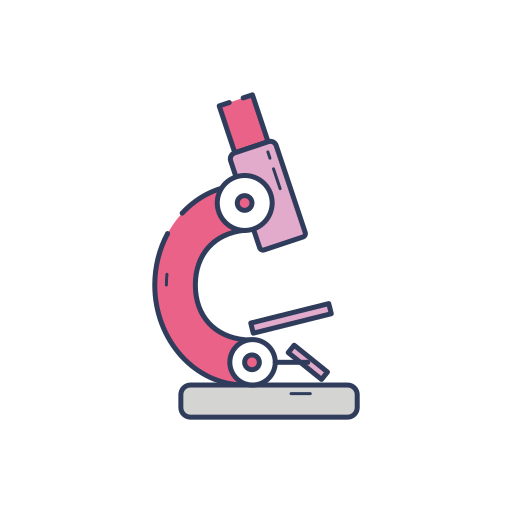**Optional reading**: This section involves some details that you will not be tested on but might find helpful to read. 

Here, we set the settings for the ode solver, `ode45`. Just like a laundry machine where you can choose the temperature of the water and other preferences, we can do the same here! Excep that instead of water temperature, we set an error tolerance with '**RelTol'** (roughly speaking, it determines the number of 'correct' digits in the solution). The second input, '**NonNegative**', tells `ode45` what components of the solution should be non-negative. Since the solutions to this set of equations are population number and negative population doesn't make sense, we specify that all solution components, susceptible, infected, and recovered must be non-negative. (For example, talking about -5 people at the store does not make sense).

options = odeset('RelTol', 1e-4, 'NonNegative', [1 2 3]);

Now we use ode45 to solve Equation 1. We use `[t,pops]` to store the solution where `pops` is an array that contains both prey and predator population solutions in separate columns. 

`@(t,pops) SIR(t,x,beta,alpha) `is a function (found at the end of this guide in the functions section) that contains Equation 1a, Equation 1b, and Equation 1c.


[t,pops] = ode45(@(t,x) SIR(t,x,beta,mu), [0 T_final], [S0 I0 R0], options);
% Pop = sum(x(end),'all')
% options = odeset('RelTol', 1e-4, 'NonNegative', [1 2 3 4]);
% [t2,pops] = ode45(@(t,x) SIRwQ(t,x,beta, mu,Gamma,d2,delta,a1,a2,gamma), [0 T_final], [S0 I0 Q0 R0], options);

Now, let's separate out the columns in `pops `so that we can refer to each one independently:

S = pops(:,1);
I = pops(:,2);
R = pops(:,3);
% R = pops(:,4);

## Graphs

Let's visualize the results. We will plot all results on the same graph:

figure
plot(t,pops, 'LineWidth',3, 'LineStyle','-');hold on;
% plot(t2,I, 'LineWidth',3, 'LineStyle','--');
% plot(t2,R, 'LineWidth',3, 'LineStyle','-.');
% show the legend
legend('Susceptible', 'Infected','Q ','Recovered');

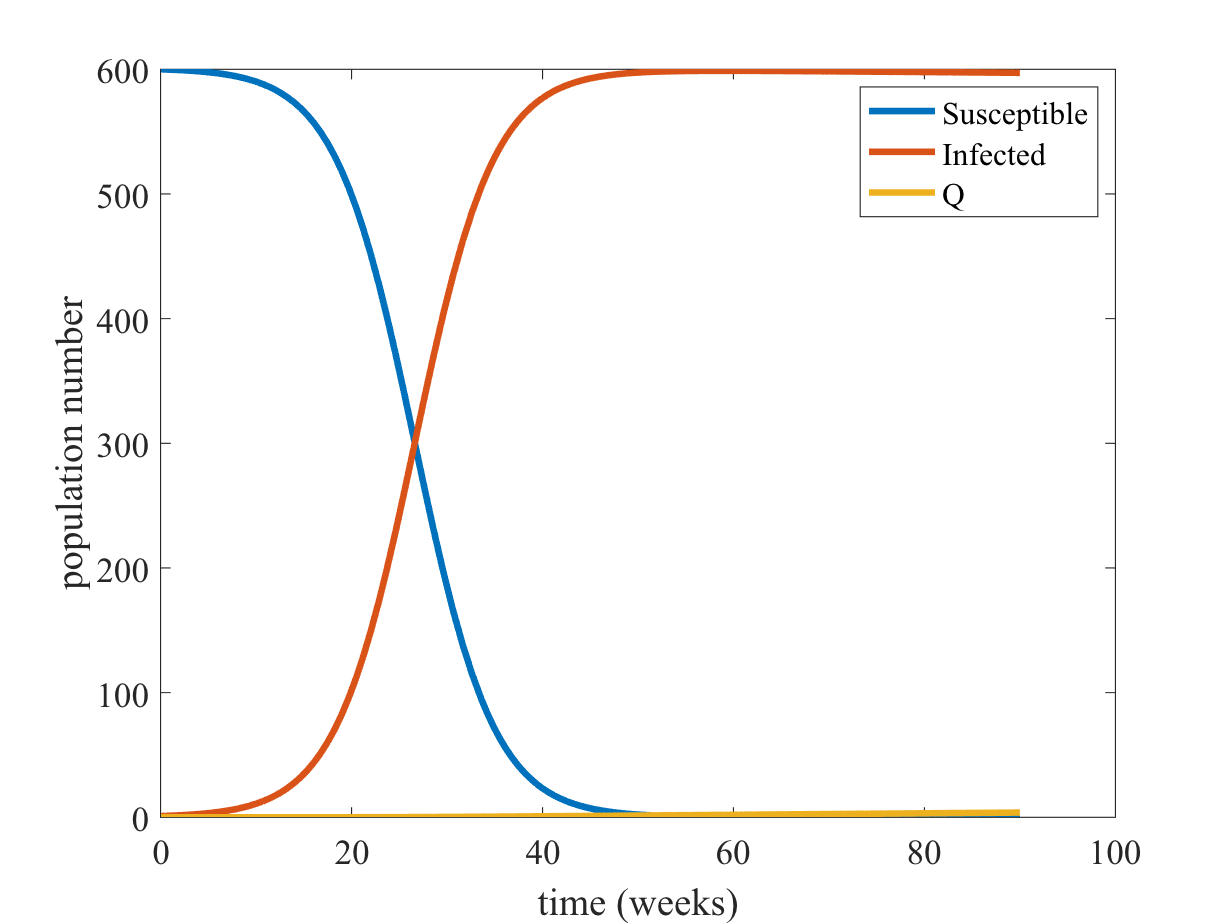

% increase the font size
set(gca, 'fontsize', 16);
set(gca, 'fontName','Times New Roman');
% insert label for the x-axis
xlabel('time (weeks)')
% insert label for the y-axis
ylabel('population number')

## Questions

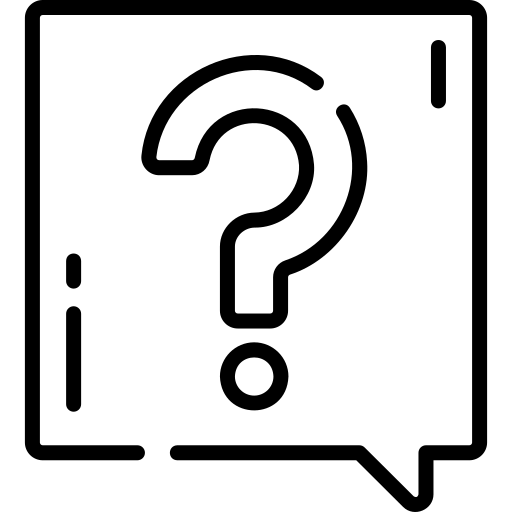 **Question 1:** Play around with the value of beta (infection rate) and watch what happens in the graph. What happens to the peak of the infected curve when you increase the value of infection rate?

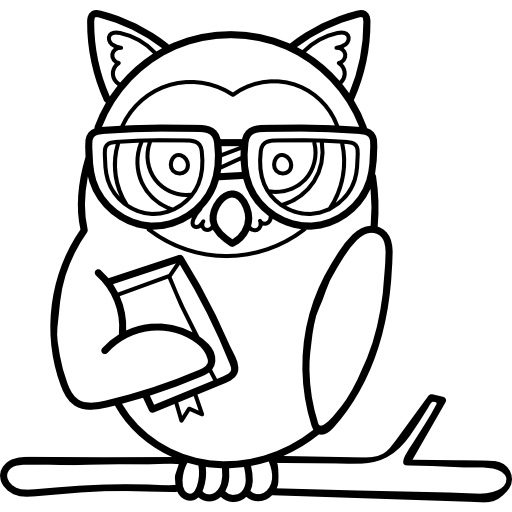  **Owl Tip on Question 1: **You may need to increase `T_final.`

  **Owl Tip 2 on Question 1: **You can visually estimate the peak. Or if you wanted a fast (or more accurate) way, you can check for the maximum of the peak by running the following code

 **Question 2:** Play around with the value of alpha (recovery rate) and watch what happens in the graph. What happens to the peak of the infected curve when you increase the value of recovery rate?

 **Question 3:** The disease in this example is not deadly, and death due to other circumstances are not included in this model. Check that the sum of the total population (S, I, and R) stays constant over time.

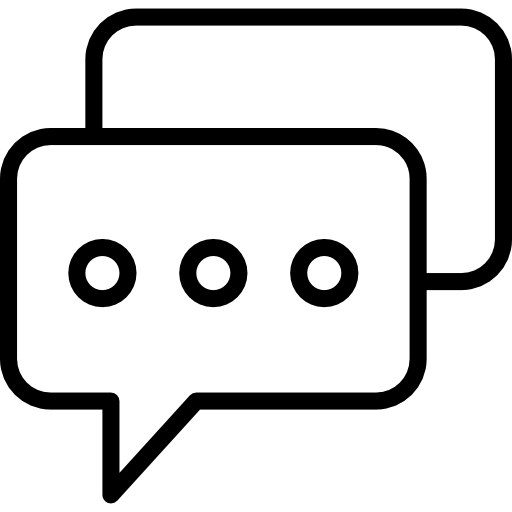 **Question 4:** What concepts are still confusing? What more examples can help? What skills do you need more help with?

 **Question 5:** Can you think of some of the limitations of the prey-predator model?

## Functions

function dx = SIR(t, x, b, d)
  dx = [0; 0; 0];
  beta = b; 
  alpha = d;

  dx(1) = -beta * x(1) * x(2);
  dx(2) = beta * x(1) * x(2) - alpha * x(2);
  dx(3) = alpha * x(2);
end 


function dx = SIRwQ(t, x, beta, mu,Gamma,d2,delta,a1,a2,gamma)
  dx = [0; 0; 0;0];

  dx(1) = Gamma - beta * x(1)* x(2)/(x(1)+x(2)+x(4))  - d2*x(1);
  dx(2) = beta/(x(1)+x(2)+x(4)) * x(1) * x(2) - (mu+d2+delta+a1) * x(2);
  dx(3) = delta*x(2)-(gamma+d2+a2)*x(3);
  dx(4) = mu * x(2) + gamma*x(3) - d2*x(4);
end 
  